clear 

fprintf("Subamortiguada (0 < E < 1)")

Subamortiguada (0 < E < 1)


E=0.5;       %coeficiente de amortiguamiento
wn=1;       %frecuencia natural no amortiguada
wd=wn*sqrt(1-E^2) %frecuencia de amortiguamiento

wd = 0.8660

sigma=E*wn

sigma = 0.5000

%a)
syms s

f=((wn^wn))/((s^2 + 2*E*wn*s + wn^2));
[n, d]=numden(f);
fdt=tf(sym2poly(n),sym2poly(d))


fdt =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



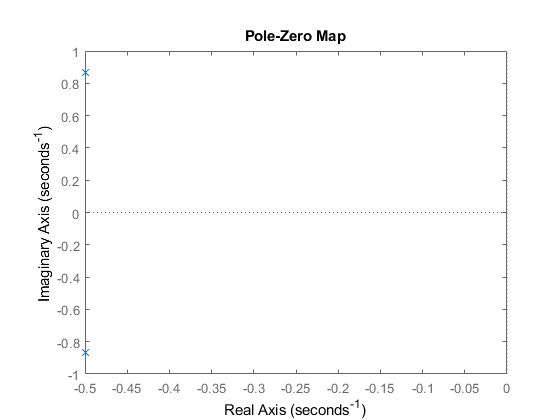


%hacemos pzmap para ver donde colocamos los polos/ceros
pzmap(fdt)


f_con_polo_adicional = ((wn^wn))/((s^2 + 2*E*wn*s + wn^2)*(s+1));
[n, d]=numden(f_con_polo_adicional);
fdt_con_polo_adicional=tf(sym2poly(n),sym2poly(d))


fdt_con_polo_adicional =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



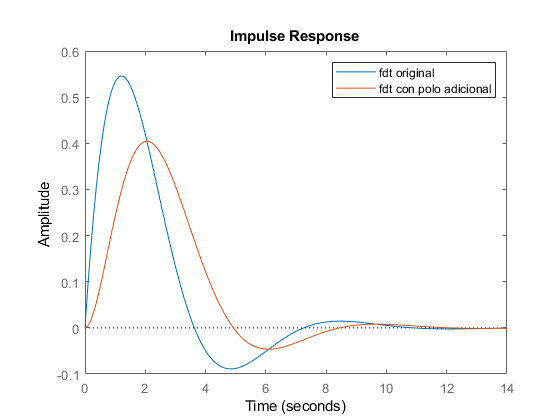


impulse(fdt) 
hold on
impulse(fdt_con_polo_adicional) 
legend('fdt original','fdt con polo adicional')
hold off



%b)
f_con_cero_adicional = ((wn^wn)*(s+1))/((s^2 + 2*E*wn*s + wn^2));
[n, d]=numden(f_con_cero_adicional);
fdt_con_cero_adicional=tf(sym2poly(n),sym2poly(d))


fdt_con_cero_adicional =
 
     s + 1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



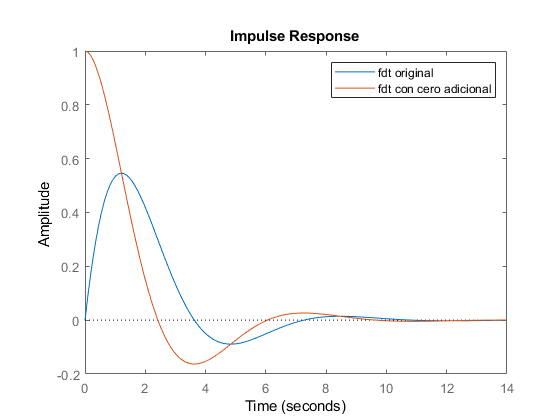


impulse(fdt) 
hold on
impulse(fdt_con_cero_adicional) 
legend('fdt original','fdt con cero adicional')
hold off